M130 Final S23

For the final all images are of cell nuclei or membranes that need to be segmented. Use everything we've learned in class so far to help you achieve a good quality result. Consider whether the image would benefit from background subtraction, noise reduction by Gaussian filtering, feature enhancement by a derivative or laplacian of a gaussian, segmentation via automatic or manual thresholding, and fine tuning via the watershed transform. Of these, you must at least:

- Apply a Gaussian filter for denoising (pick an appropriate value for c) **(2 pts)**

- Test different thresholding approaches and pick the best one **(2 pts)**

- Clean up the initial segmentation via mathematical morphology **(3 pts)**

- Measure some basic object shape metrics - use regionprops to measure object area, solidity, eccentricity, and/or perimeter. Do any of these metrics seem to show which objects are likely not correctly segmented? **(3 pts)**

- Perform watershed segmentation via either the distance transform or the laplacian of a Gaussian **(3 pts)**

- Use binary logic to combine the watershed results with the segmentation and perform connected components labeling with bwlabel **(2 pts)**

- Re-measure some of the metrics from #4, does the distribution of that metric seem to suggest a better job done at segmentation after the watershed? **(3 pts)**

- Any final pieces of feedback for the class? Please answer these specific questions:

Feedback Questions: **(2 pts)**

Do you think you might have preferred to have had a single cohesive project to work on over the course of the quarter in groups rather than these discrete lab assignments? 

Would you have liked to have spent less time on covering each aspect of the core image analysis pipeline in exchange for the opportunity to explore a more advanced method with a group? 

Would you have preferred to use Python in this class or did you like MATLAB? 

**Extra credit opportunities**

Pick just 1 of these options to attempt for extra credit:

- Design prompts to have ChatGPT generate MATLAB code to segment your image. Be as specific or general as you'd like but the code must successfully run. Compare the script and results that ChatGPT generated with your own and compare/contrast. What did the ChatGPT code do better, what did it do worse? Did it use approaches you're familiar with from class? **Submit the ChatGPT code in a separate mlx or m file along with your code as well as screenshots of your prompts for it.** It's ok to manually edit the ChatGPT code to make sure it loads the right image, but otherwise try your best to talk it through generating the script on its own. **(Up to 5 points)**

- Try something new: use Google, StackOverflow, and the Mathworks File Exchange to find alternative implementations of segmentation algorithms, different thresholding algorithms, and different noise reduction algorithms. Try the scripts / functions you find on your own images and compare and contrast the results with that of your own script. Try your best to explain how the code / method you found works. Upload a separate script of your own using this code as well as any additional scripts / functions you may have downloaded. Include the URL where you found the information in a comment in this script. **(Up to 5 points)**

- Use machine learning: Download Fiji (https://fiji.sc/) and follow the instructions to install a deep learning based segmentation pipeline like Stardist (https://imagej.net/plugins/stardist) or CellPose (https://github.com/BIOP/ijl-utilities-wrappers). These pipelines should be able to run on a laptop (albeit slowly). Get the pipeline working and use it to segment your data. Compare the results after adjusting the available parameters with the results from your own code. Upload an image of the deep learning generated segmentation mask alongside your code for the final.

%Read and display your image.
info = imfinfo("2D_Image_9.tif")

info = struct with fields:
                     Filename: 'C:\Users\wangs\Downloads\2D_Image_9.tif'
                  FileModDate: '08-Jun-2023 10:11:18'
                     FileSize: 327948
                       Format: 'tif'
                FormatVersion: []
                        Width: 640
                       Height: 512
                     BitDepth: 8
                    ColorType: 'grayscale'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'Uncompressed'
    PhotometricInterpretation: 'BlackIsZero'
                 StripOffsets: 268
              SamplesPerPixel: 1
                 RowsPerStrip: 512
              StripByteCounts: 327680
                  XResolution: []
                  YResolution: []
               ResolutionUnit: 'Inch'
                     Colormap: []
          PlanarConfiguration: 'Chunky'
                    Ti

img = imread("2D_Image_9.tif")

img = 512×640 uint8 matrix
    5    8    3    3    5    5    5    5    5    5    5    5    5    6    6    6    5    5    5    5    5    5    5    5    5   10    8    8    7    3    1    3    3    8    3    3    5    5    5    5    5    5    5    3    3    8    5    5    8    8
    5    5    3    3   13    8   10    5    5    5    5    5    5    6    6    6    5    5    5    5    4    5    5    5    6    6    5    8    3    3    3    3    3    8    3    3    5    5    5    5    5    5    3    8    3    5    6    6    5    8
    5    5    3    7    3    3    3    8    5    5    5    5    5    5    6    6    5    5    8    3    8    3    5    5    6    6    6    5    8    8    8    8    8    3    3    3    5    6    5    5    5    5    4    5    5    5    6    6    5    8
    6    5    5    3    3    3    8    8    5    5    3    3    8    8    6    6   10    5    3    3    3    8    5    5    6    6    6    6    5    8    5    5    3    8    3    3    5    6    5    5    5    5    5    5

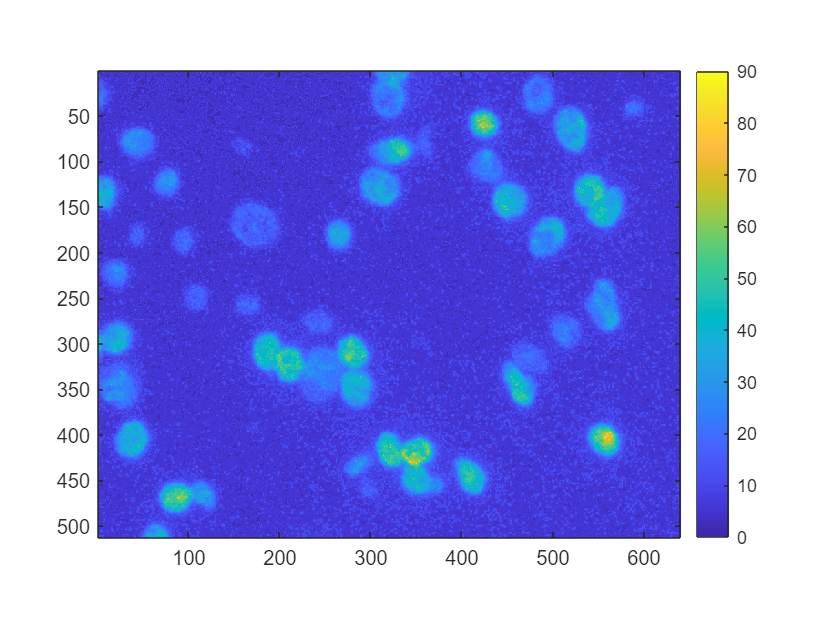

imagesc(img)
colorbar 
axis image

%Filter and/or background subtract your image

perform background subtraction 

%bg = imopen(img,strel('disk',15)); 
%img_bg = img-bg;
%imagesc(img_bg)
%colorbar 
%axis image

now filtering 

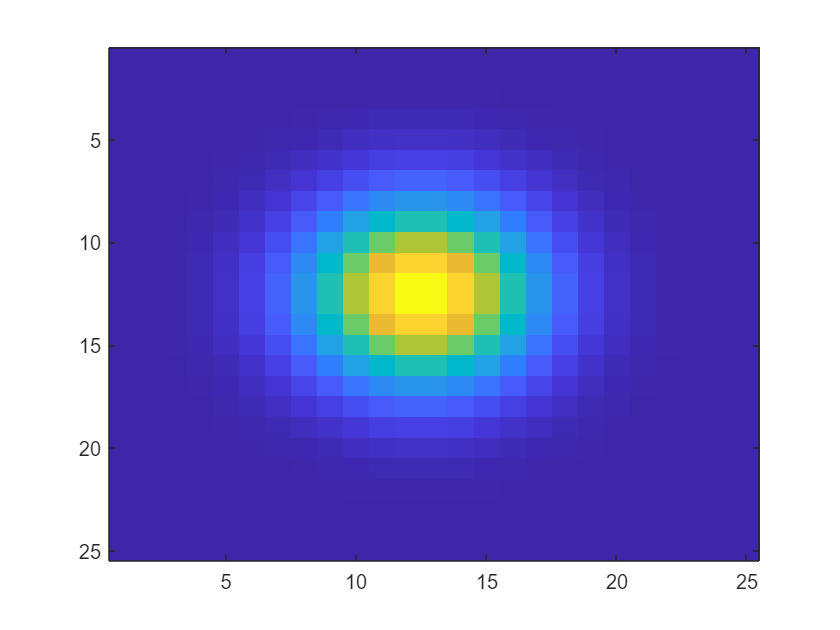

m = 25;
n = 25;
gaussian = zeros(m,n);
c = 3; 
for x=1:n
    for y=1:m
        sq_dist = (x-n/2)^2 + (y-m/2)^2; 
        gaussian(y,x) = exp(-1*sq_dist/(2*c*c)); 
    end
end
gaussian = gaussian./sum(gaussian(:)); 
imagesc(gaussian)

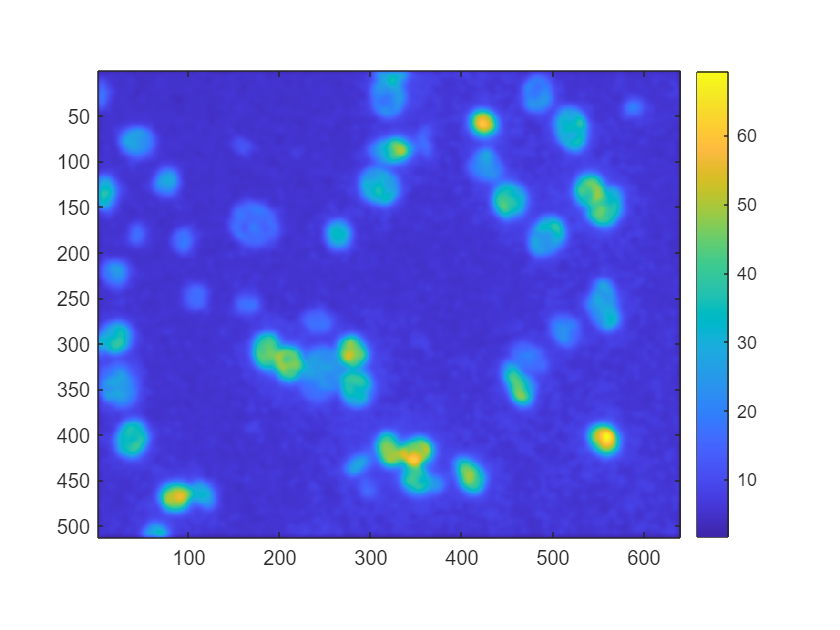


img_blur = conv2(img,gaussian,'same');
imagesc(img_blur)
colorbar
axis image

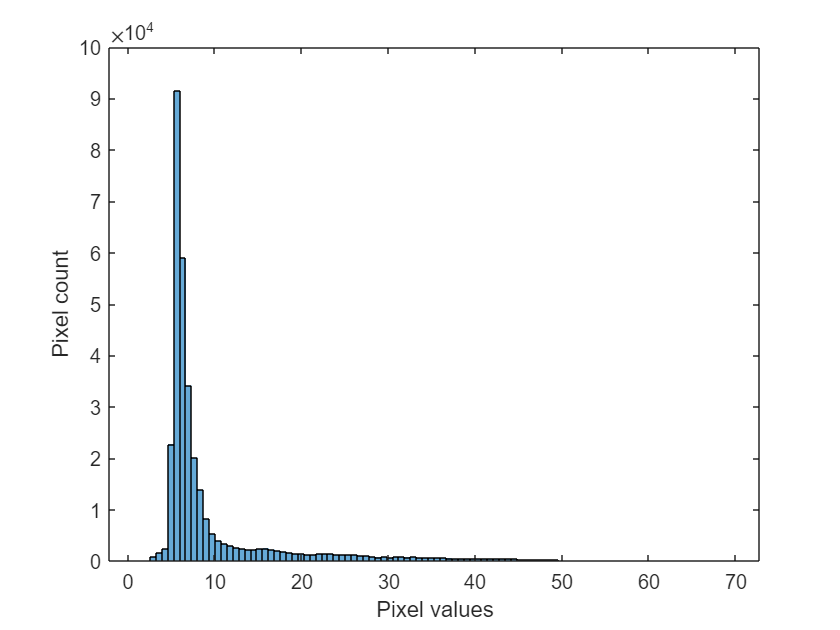

%Try different thresholding strategies and pick the one that works best

bg = imopen(img_blur,strel('disk',100));
img_bg = img_blur-bg;

histogram(double(img_blur(:)), 100)
xlabel('Pixel values')
ylabel('Pixel count')

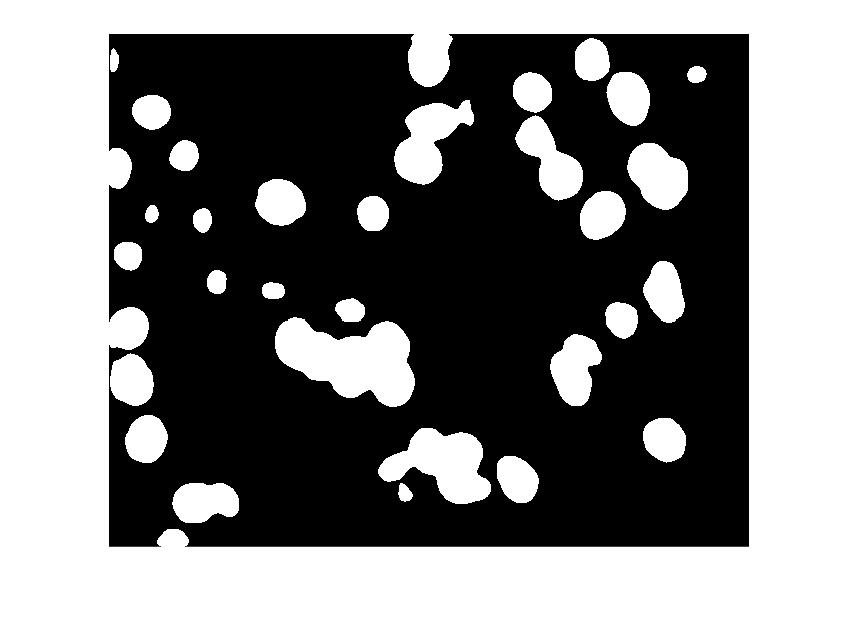

thresh = 13; 
bw = img_blur > thresh; 
imshow(bw)

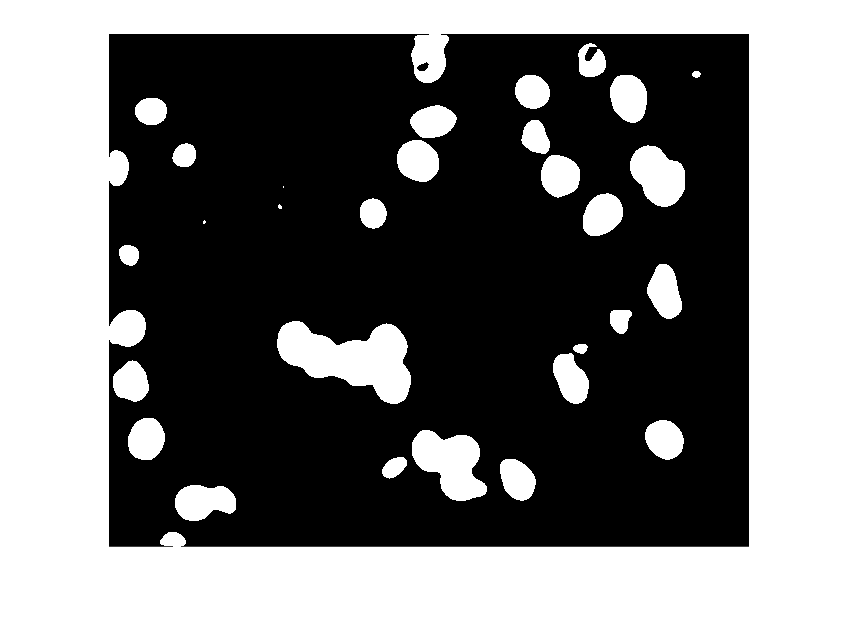

otsu = imbinarize(uint8(img_blur), "global");
imshow(otsu)

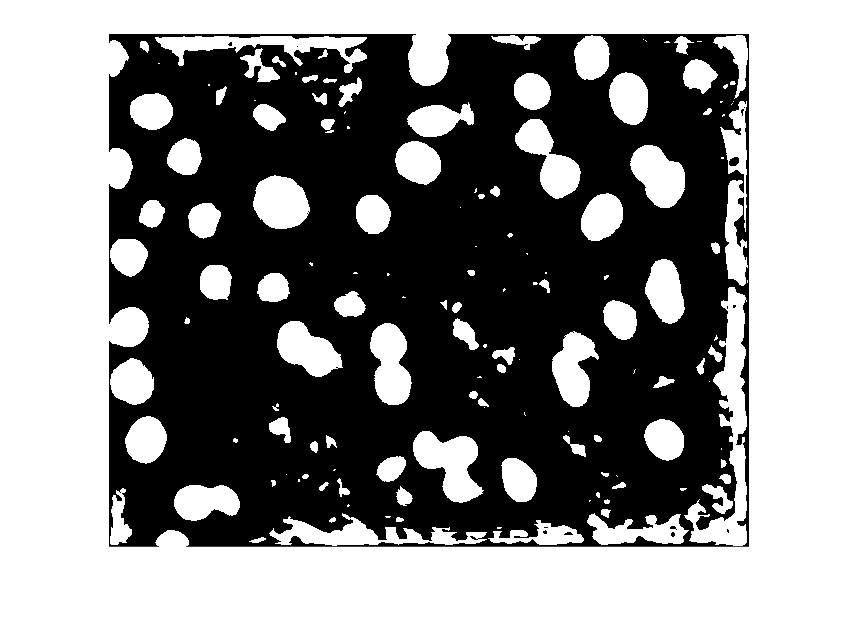

adaptive = imbinarize(uint8(img_blur), "adaptive"); 
imshow(adaptive) 

Manual thresholding method seems to be performing better, we will be using it for the rest of the lab. 

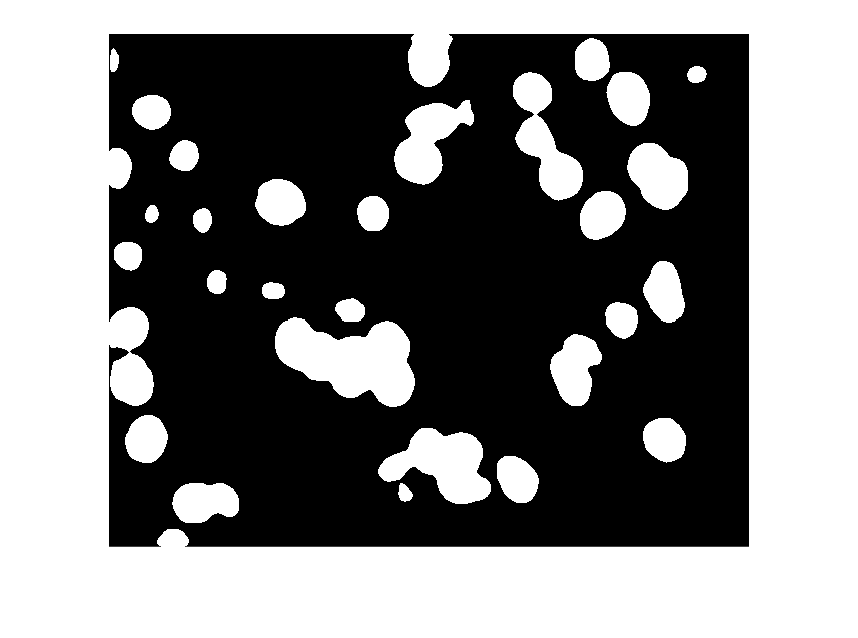

%Clean up your segmentation via mathematical morphology
bw1 = bwareaopen(bw,100);
bw2 = imclose(bw1,strel('disk',2));
imshow(bw2)

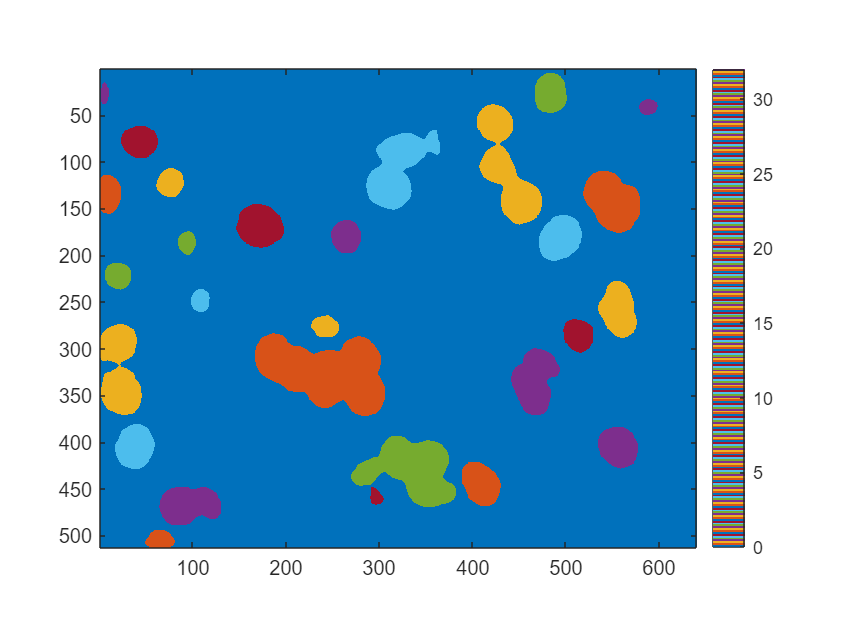

%Measure some basic object shape metrics - use regionprops to measure object area, solidity, eccentricity, and/or perimeter.
[L,N] = bwlabel(bw2);
imagesc(L)
colormap lines
colorbar
axis image

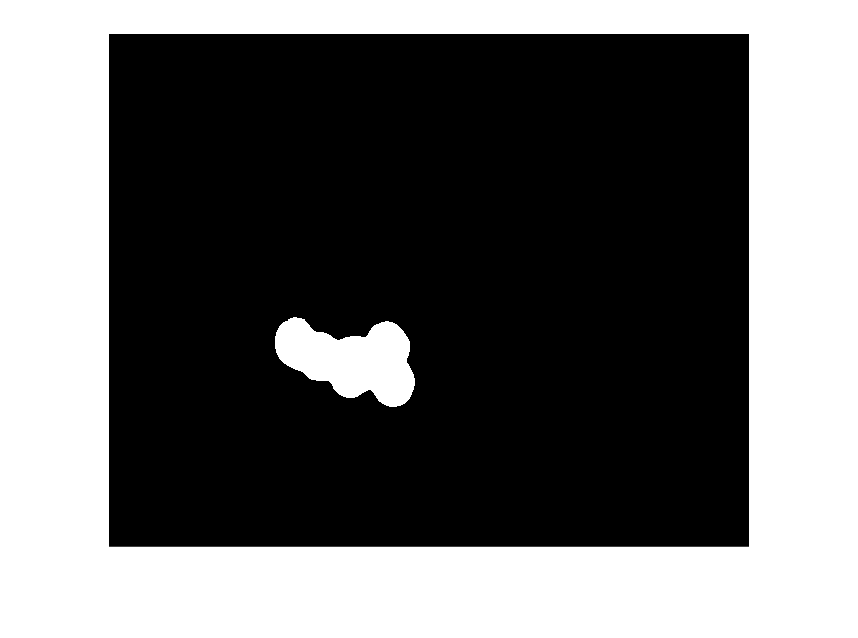

imshow(L == 15)

STATS = regionprops(bw2,'Area', 'Solidity', 'Eccentricity', 'Perimeter')

STATS = 32×1 struct array with fields:
    Area
    Eccentricity
    Solidity
    Perimeter


%note: Measure from lecture13 demo, region property from "Extract" section

**Do any of these metrics seem to show which objects are likely not correctly segmented?**

Yes, the STATS indicates certain objects not being fully segmented. For example, I pulled out object 15 which has a anolmalous perimeter of 403.628, and an outlier area of 7968, which I extracted in an above image showing its eccentric shape--- ther is no nuclei in the object. Furthermore, the table was only able to discern 32 separate objects in the image, which is lower than the real amount of nuclei as seen in the original image, this means that the image can be further segmented. 

Some other object examples are shown below: 

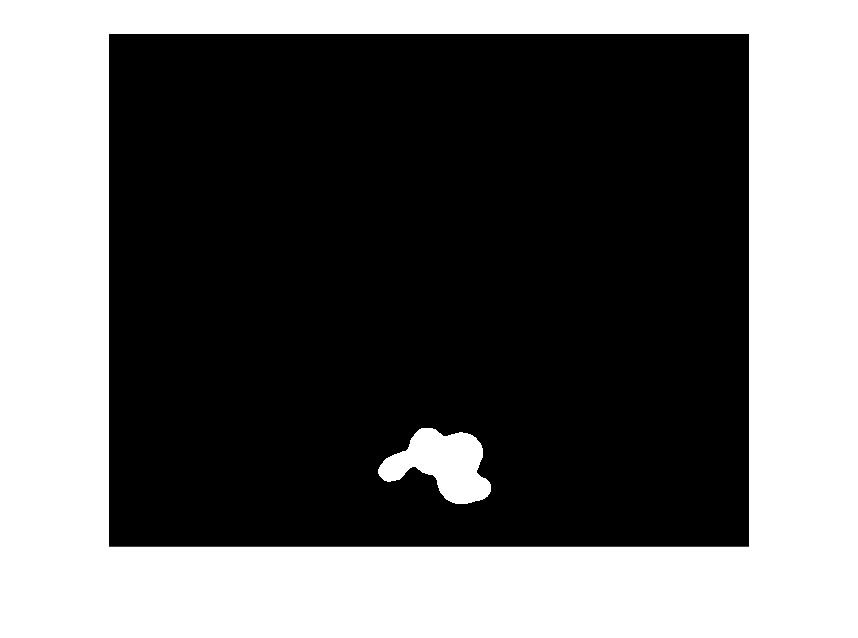

imshow(L == 18) % this one has a high area and large perimeter also 

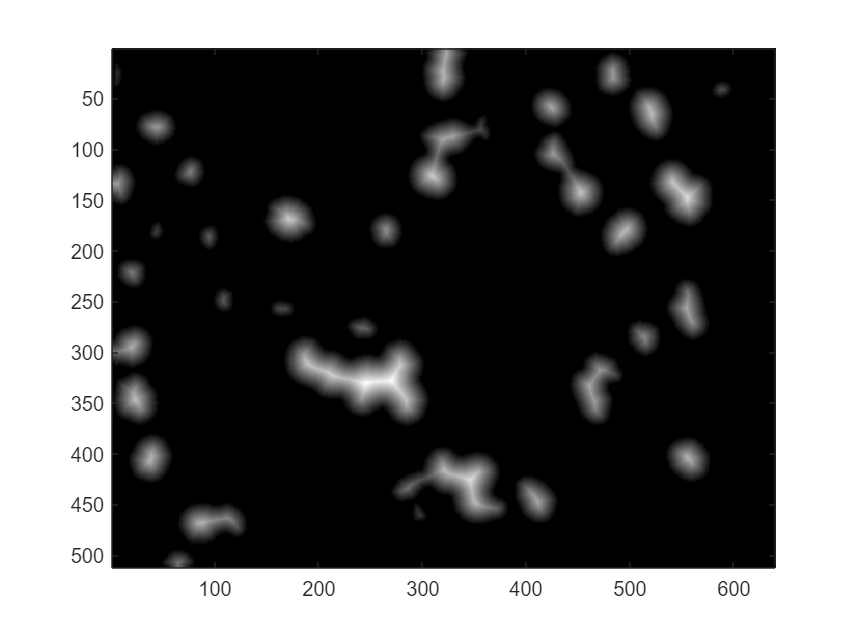

%Perform watershed segmentation via either the distance transform or the laplacian of a Gaussian
D = bwdist(~bw);
imagesc(D);
colormap gray

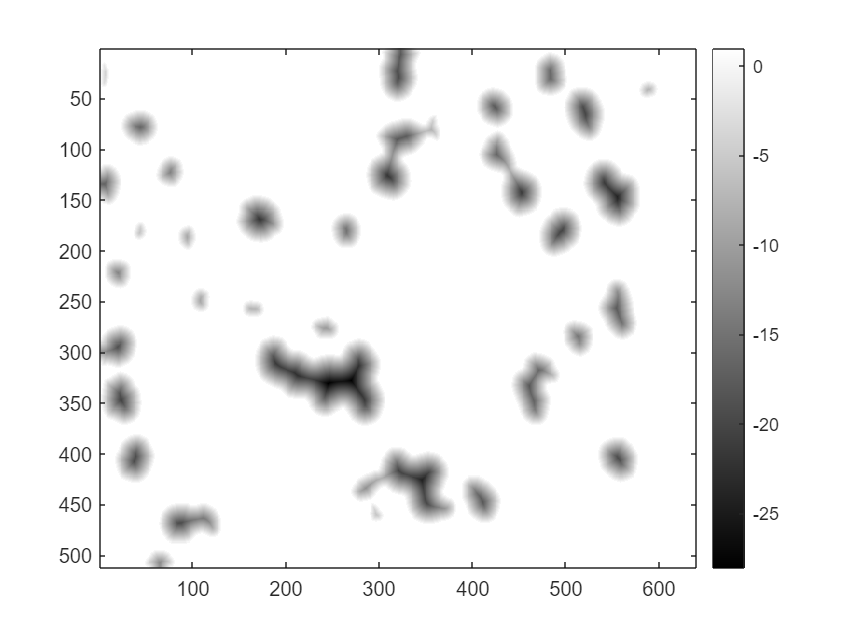

%colorbar
D = imcomplement(D);
imagesc(D);
colorbar

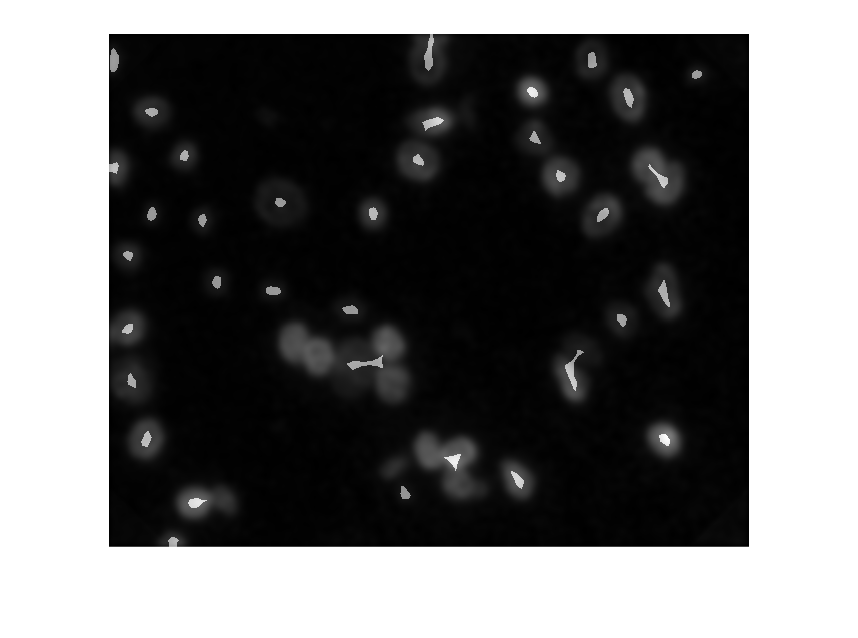

mask = imextendedmin(D, 4);
imshowpair(img_bg,mask,'blend')

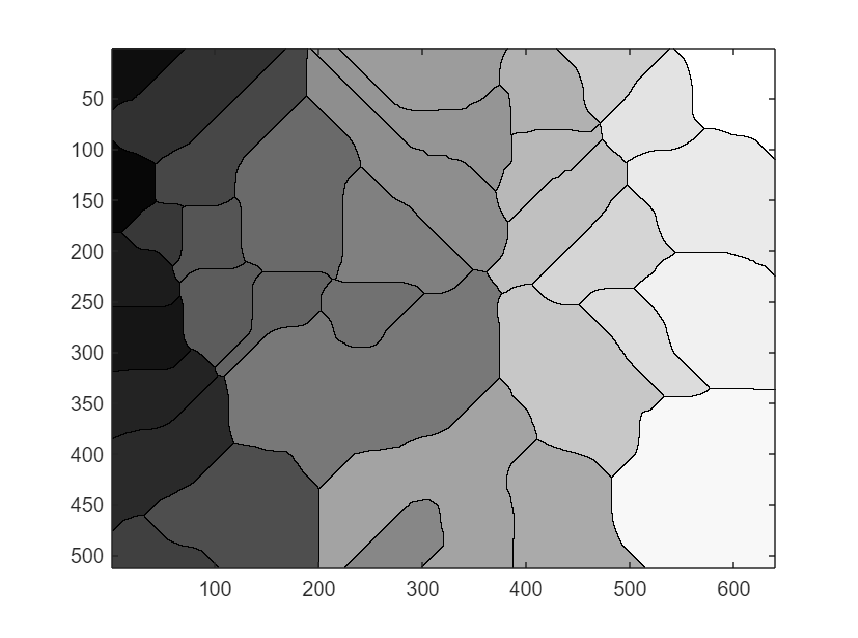

D2 = imimposemin(D,mask);
Ld2 = watershed(D2);
imagesc(Ld2)

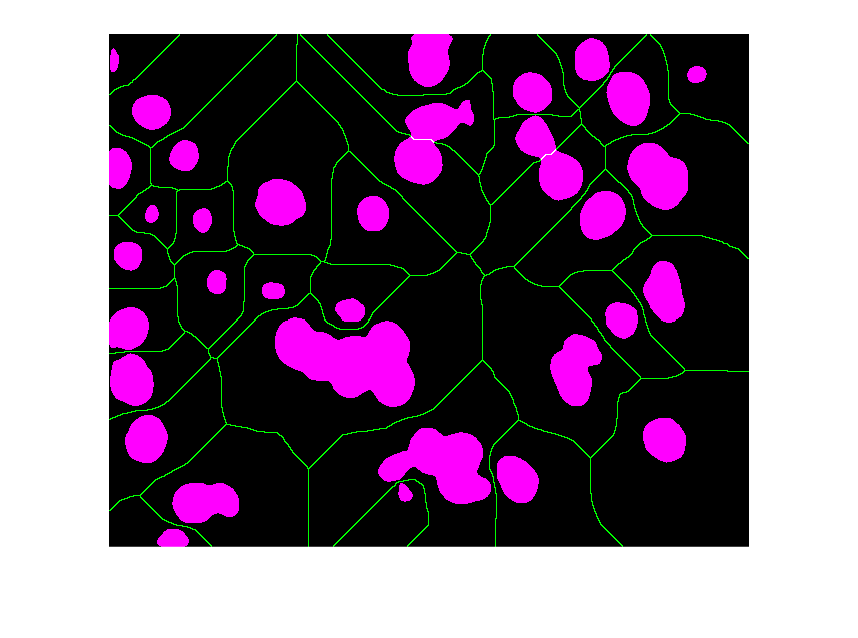

bw2 = Ld2==0;
imshowpair(bw2,bw)

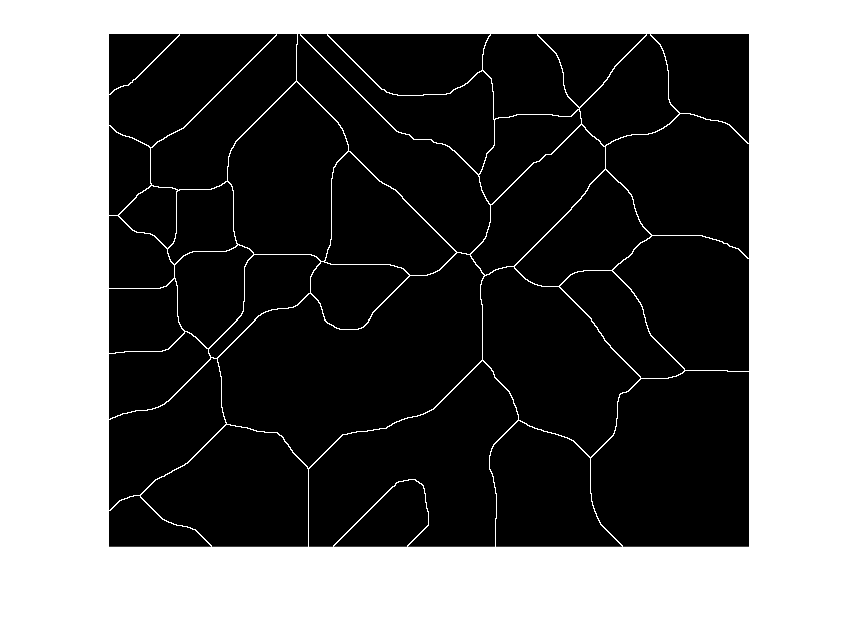

imshow(bw2)

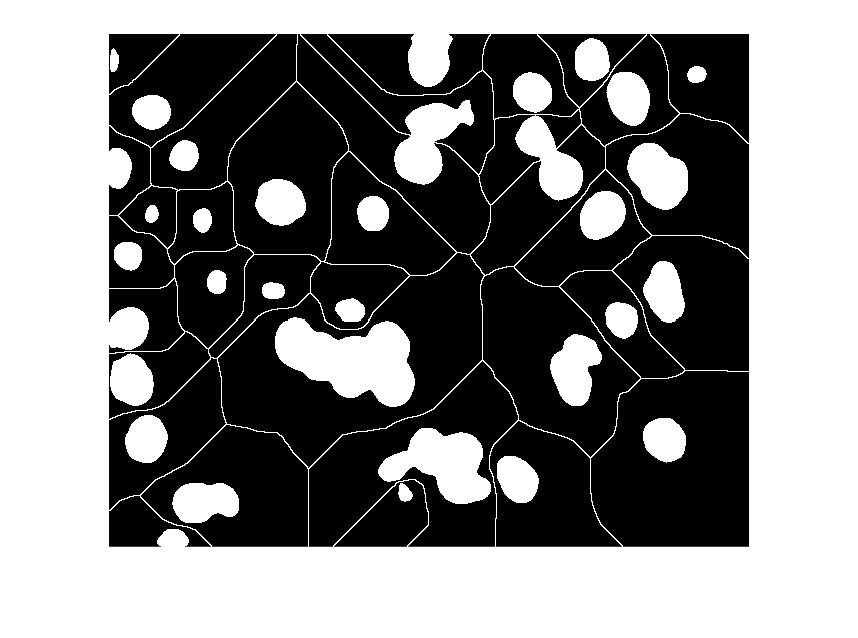

imshow(bw2|bw)

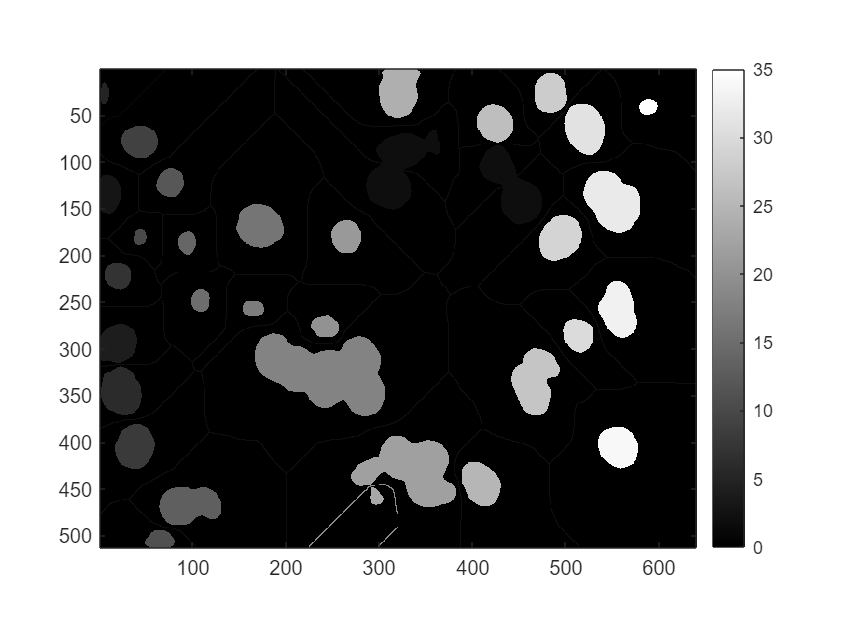

%Use binary logic to combine the watershed results with the segmentation and perform connected components labeling
[L,N] = bwlabel(bw2|bw);
imagesc(L)
colorbar
axis image

%Re-measure some of the metrics from #4
STATS = regionprops(L,'Area', 'Solidity', 'Eccentricity', 'Perimeter')

STATS = 35×1 struct array with fields:
    Area
    Eccentricity
    Solidity
    Perimeter


**Does the distribution of these metrics seem to suggest a better job done at segmentation after the watershed?**

Yes, the areas, eccentricities, solidities and perimeters are more representative of a singular nuclei than before. There are 3 more obejcts detected in the image after performing watershed thresholding, which is better than 32 objects. 

**Final Feedback for the class:**

I enjoyed the lab and class format, with each lab focusing on a single techniques. I would prefer discrete lab assignments because reinforcing the lecture notes I take in class is important. I would not have liked spending less time on covering each aspect of the core image analysis pipeline, because I would feel rushed. Lastly, I would have preferred python more just because of previous experience, but I'm sure the students who are more adept at Matlab would say otherwise. 

I also enjoyed the tutorial guidance for us to follow along at each section. The final week's lecture on neural networks was excellent, I really enjoyed it. Thank you Professor, TAs for a fun class. Have a great summer! 